# Sistemas e Sinais - T2

## Ettore Padula Dalben - 20.00387-0

### 1.1 - 1

Formulação e equações


$$D_n =\frac{1}{T_0 }\cdot \int_{T_0 } g\left(t\right)\cdot e^{-j\cdot \omega_0 \cdot n\cdot t} \textrm{dt}$$



$$G\left(\omega \right)=\int_{-\infty }^{\infty } g\left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t}$$



$$\Delta \left(t\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & t<-2\\
t+2 & -2<t<0\\
-t+2 & 0<t<2\\
0 & t>2
\end{array}\right\rbrack \right\rbrace$$



$$G\left(\omega \right)=\int_{-\infty }^{-2} \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t} +\int_{-2}^0 \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t} +\int_0^2 \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t} +\int_2^{\infty } \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t}$$



$$G\left(\omega \right)=0+\int_{-2}^0 \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t} +\int_0^2 \Delta \left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t} +0$$



$$G\left(\omega \right)=\int_{-2}^0 \left(t+2\right)\cdot e^{-j\cdot \omega_0 \cdot t} +\int_0^2 \left(-t+2\right)\cdot e^{-j\cdot \omega_0 \cdot t}$$



$$G\left(\omega \right)=\frac{-e^{2\omega_0 j} +2\omega_0 j+1}{\omega_0^2 }-\frac{e^{-2\omega_0 j} +2\omega_0 j-1}{\omega_0^2 }$$



$$G\left(\omega \right)=\frac{-e^{2\omega_0 j} +2\omega_0 j+1{-e}^{-2\omega_0 j} -2\omega_0 j+1}{\omega_0^2 }$$



$$G\left(\omega \right)=\frac{4\cdot {\textrm{sen}}^2 \left({n\omega }_0 \right)}{{n^2 \omega }_0^2 }$$


### 1.1 - 2

clc;            % limpa a tela
clear all;      % limpar as variáveis
close all;      % fecha as figuras abertas

syms t n wo
j = 1i;         % normação do irracional

% Definição das equações simbólicas 
g = @(t) 2+t;
e = @(t,n,wo) exp(-j*n*wo*t);
Gw =@(w) 4*(sin(w))^2/(w^2);

% Definição das variáveis não simbólicas
To = 4;
ti = -2;
tm = 0;
tf = 2;
N = 100;

% Cálculo das formulações
Dn = (1/To) * (int(g(t)*e(t,n,wo),t,ti,tm) + int(g(-t)*e(t,n,wo),t,tm,tf));
Dn0 = (1/To) * (int(g(t),t,ti,tm) + int(g(-t),t,tm,tf));
G = Gw(n*wo)/To;

### 1.1 - 3

% Definição de variáveis até então simbólicas
wo = 2*pi/To;
n = 1;

% Aplicação e Comparação das equações para um caso
Dn1 = real(eval(Dn))

Dn1 = 0.4053

Go = eval(G);
fprintf("A diferença entre as fórmulas é: %i\n", (Dn1 - Go))       % explicitação do resultado

A diferença entre as fórmulas é: 0


### 1.1 - 4

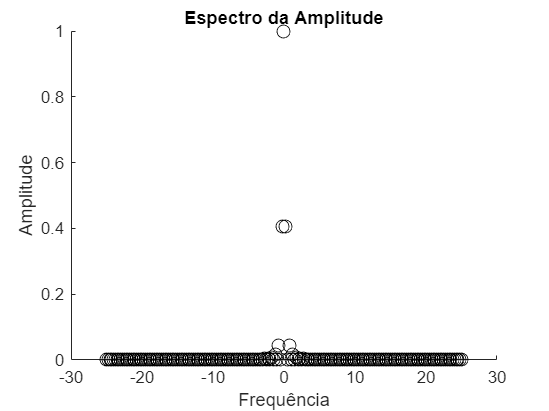

% Revaloração de variáveis para criação do gráfico
n = -N:1:N;
f = n*(1/To);

% Aplicação das equações para criação do gráfico
Dn2 = eval(Dn);
Dn2(N+1) = eval(Dn0);
Dn2 = abs(Dn2);

% Explicitar o gráfico de frequência
figure(1) 
scatter(f,Dn2, 60, "black");
title('Espectro da Amplitude');
xlabel('Frequência');
ylabel('Amplitude');


% Variáveis auxiliares para criação do gráfico de sinal
S = 0;
temp = ti:To/400:tf;

% Aplicação de uma fórmula para formar o gráfico de sinal
for i=1:2*N
    S = S + Dn2(i)*e(temp,n(i),wo);
end

% Explicitar o gráfico de sinal
figure(2)
plot(temp,S,"linewidth", 5)

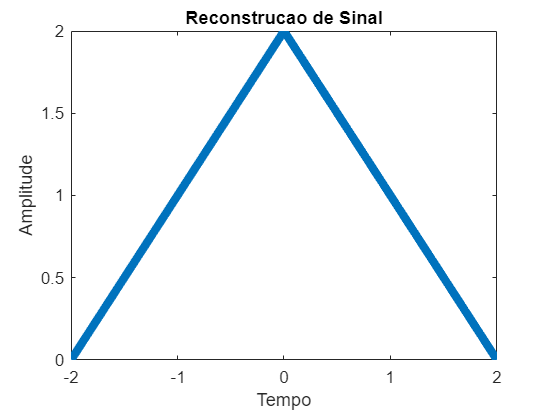

title('Reconstrucao de Sinal');
xlabel('Tempo');
ylabel('Amplitude');


% Cálculo da potência dos elementos de Dn2
Pot1 = sum(abs(Dn2).^2);

% Variáveis para o cálculo iterativo do percentual da potência
cont = 1;
CS = Dn2(N+1)^2;
p100 = CS/Pot1;

% Loop para encontrar a potência percentual desejada
while (p100 < 0.95)
    cont = cont + 1;
    CS = CS + 2*abs(Dn2(N+cont))^2;
    p100 = CS/Pot1;
end

% Explicitação dos resultados
fprintf("A segunda potência calculada é: %.5f", Pot1)

A segunda potência calculada é: 1.33333

fprintf("Foi encontrado: %.5f", p100)

Foi encontrado: 0.99638

fprintf("Será preciso um n de %i\n", cont)

Será preciso um n de 2


### 2.1 - 1

Reformulação e equações


$$G\left(\omega \right)=\frac{4\cdot {\textrm{sen}}^2 \left({n\omega }_0 \right)}{n^2 \omega_0^2 }$$



$$g\left(t\right)=\Delta \left(t-2\right)-\Delta \left(t-6\right)$$



$$\textrm{g1}\left(t\right)=g\left(t-t_0 \right)$$



$$G\left(\omega \right)=\int_{-\infty }^{\infty } \textrm{g1}\left(t\right)\cdot e^{-j\cdot \omega_0 \cdot t}$$



$$G\left(\omega \right)=\int_{-\infty }^{\infty } g\left(t-t_0 \right)\cdot e^{-j\cdot \omega_0 \cdot t}$$



$$\textrm{G1}\left(\omega \right)=e^{-j\cdot \omega_0 \cdot t_0 } \int_{-\infty }^{\infty } g\left(x\right)\cdot e^{-j\cdot \omega_0 \cdot x}$$



$$\textrm{G1}\left(\omega \right)=e^{-j\cdot \omega_0 \cdot t_0 } \cdot G\left(\omega \right)$$



$$\textrm{G1}\left(\omega \right)=e^{-2{j\omega }_0 } \cdot G\left(\omega \right)$$



$$\textrm{G2}\left(\omega \right)=e^{-6j\omega_0 } \cdot G\left(\omega \right)$$



$$\textrm{G3}\left(\omega \right)=\textrm{G1}\left(\omega \right)-\textrm{G2}\left(\omega \right)$$



$$\textrm{G3}\left(\omega \right)=e^{-2{j\omega }_0 } \cdot G\left(\omega \right)-e^{-6j\omega_0 } \cdot G\left(\omega \right)$$



$$\textrm{G3}\left(\omega \right)=\left(e^{-2{j\omega }_0 } -e^{-6{j\omega }_0 } \right)\cdot G\left(\omega \right)$$



$$\mathrm{G3}\left(\omega \right)=\left(e^{-2{j\omega }_0 } -e^{-6j\omega_0 } \right)\cdot \frac{4\cdot {\mathrm{sen}}^2 \left({n\omega }_0 \right)}{n^2 \omega_0^2 }$$


### 2.1 - 2

% Redefinição das variáveis
syms t n wo
To = 8;
ti = -4;
tf = 4;

% Reformulação, adequando às alterações
Dn = (1/To) * (int(g(t)*e(t,n,wo),t,ti,tm) + int(g(-t)*e(t,n,wo),t,tm,tf));
Dn0 = (1/To) * ((int(g(t-2),t,ti,tm) - int(g(-t+2),t,tm,tf))-(int(g(t-6),t,ti,tm) - int(g(-t+6),t,tm,tf)));
G = Gw(n*wo)/To;
Dn3 = (1/2) * Dn*(e(2,1,wo)-e(6,1,wo));

### 2.1 - 3

% Redefinição das variáveis
wo = 2*pi/To;
n = 1;

% Obtenção do valor de Dn
Dn6 = eval(Dn3)

Dn6 = 0.0000 - 0.8106i

Dn4 = eval(Dn/2)

Dn4 = 0.4053 + 0.0000i

Go = eval(G)

Go = 0.4053

Dn5 = Go*(e(2,1,wo)-e(6,1,wo))

Dn5 = 0.0000 - 0.8106i


% Aplicação e Comparação das equações para um caso
fprintf("A diferença entre as fórmulas primárias é: %i\n", (Dn4 - Go))

A diferença entre as fórmulas primárias é: 5.551115e-17


fprintf("A diferença entre as segundas secundárias é: %i\n", (Dn6 - Dn5))

A diferença entre as segundas secundárias é: 2.481653e-17


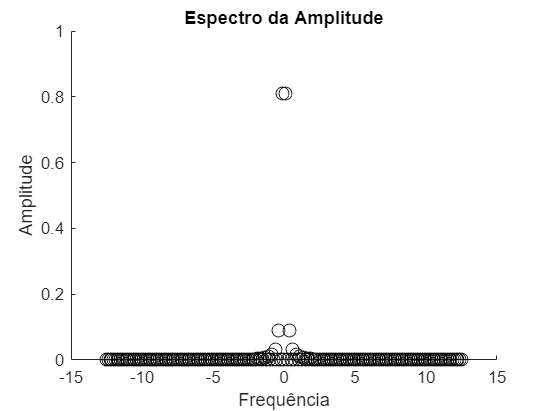


% Revaloração de variáveis para criação do gráfico
n  = -N:1:N;
f = n*(1/To);

% Aplicação das equações para criação do gráfico
Dn3 = eval(Dn3);
Dn3(N+1) = 0; %eval(Dn0/16);
Dn3 = abs(Dn3);

% Explicitar o gráfico de frequência
figure(3) 
scatter(f,Dn3, 60, "black");
title('Espectro da Amplitude');
xlabel('Frequência');
ylabel('Amplitude');


% Variáveis auxiliares para criação do gráfico de sinal
S = 0;
temp = 0:To/200:8;

% Aplicação de uma fórmula para formar o gráfico de sinal
for i = 1:2*N
    Del2 = Dn3(i)*e(2,n(i),wo);
    Del6 = Dn3(i)*e(6,n(i),wo);
    Aux = (Del2 - Del6)*e(temp,n(i),-wo);
    S = S + Aux;
end

% Explicitar o gráfico de sinal
figure(4)
plot(temp, S,"linewidth", 5)

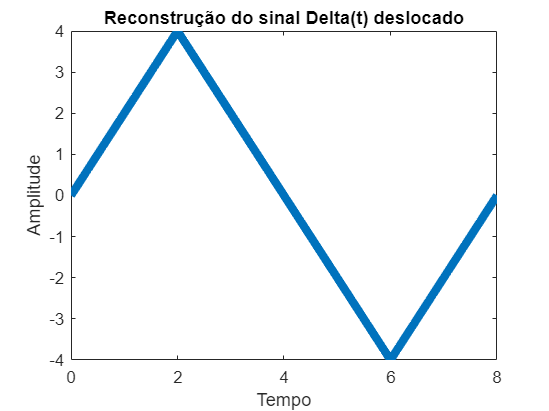

title('Reconstrução do sinal Delta(t) deslocado');
xlabel('Tempo');
ylabel('Amplitude');

### 2.1 - 4

% Cálculo da potência dos elementos de Dn6
Pot2 = sum(abs(Dn3).^2);

% Variáveis para o cálculo iterativo do percentual da potência
cont = 1;
CS = Dn3(N+1)^2;
p100 = CS/Pot2;

% Loop para encontrar a potência percentual desejada
while (p100 < 0.95)
    cont = cont + 1;
    CS = CS + 2*abs(Dn3(N+cont))^2;
    p100 = CS/Pot2;
end

% Explicitação dos resultados
fprintf("A segunda potência calculada é: %.5f", Pot2)

A segunda potência calculada é: 1.33333

fprintf("Foi encontrado: %.5f", p100)

Foi encontrado: 0.98553

fprintf("Será preciso um n de %i\n", cont)

Será preciso um n de 2
